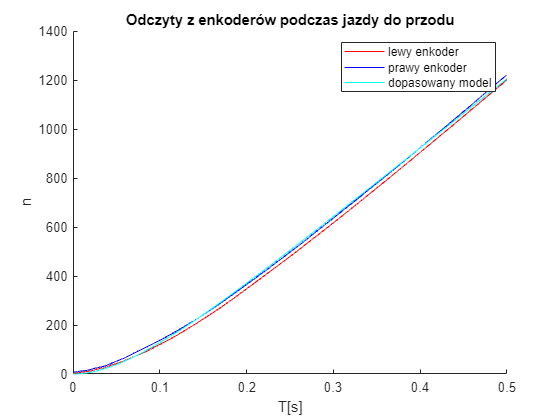

clear all
close all

model = tf([1580], [0.074 1 0])/32/pi*180;
[y, t_out] = step(model, 0.5);
A_read = readmatrix("mess_5000_2000hz_2.csv");
A = (A_read - 200);
left_enc = A(:,1);
right_enc = A(:,2);
time_enc = linspace(0, 0.5, 1000)';
hold on
plot(time_enc, right_enc, 'r-')
plot(time_enc, left_enc, 'b-')
plot(t_out, y, 'c')
xlabel("T[s]")
ylabel("n")
title("Odczyty z enkoderów podczas jazdy do przodu")
legend("lewy enkoder", "prawy enkoder", "dopasowany model")

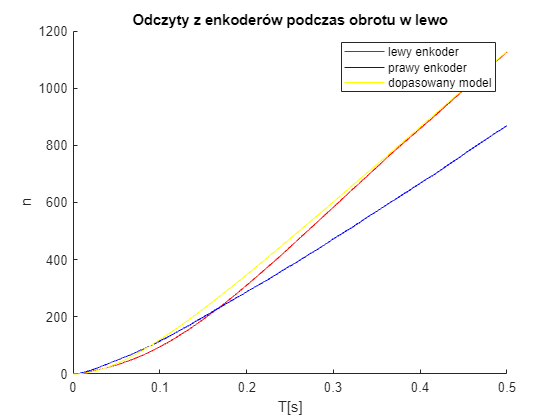

figure

model = tf([1480], [0.074 1 0])/32/pi*180;
[y, t_out] = step(model, 0.5);
A_read = readmatrix("mess_5000_2000hz_spin_1.csv");
A = (A_read - 32000);
left_enc = -A(:,1);
right_enc = A(:,2);
time_enc = linspace(0, 0.5, 1000)';
hold on
plot(time_enc, right_enc, 'r-')
plot(time_enc, left_enc, 'b-')
plot(t_out, y, 'y')
xlabel("T[s]")
ylabel("n")
title("Odczyty z enkoderów podczas obrotu w lewo")
legend("lewy enkoder", "prawy enkoder", "dopasowany model")

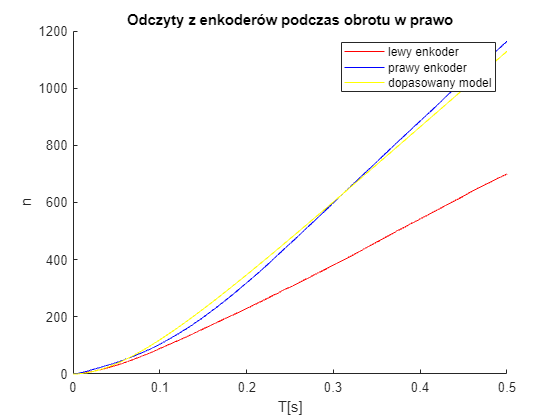


figure

model = tf([1480], [0.074 1 0])/32/pi*180;
[y, t_out] = step(model, 0.5);
A_read = readmatrix("mess_5000_2000hz_spin_rev_2.csv");
A = (A_read - 32000);
left_enc = A(:,1);
right_enc = -A(:,2);
time_enc = linspace(0, 0.5, 1000)';
hold on
plot(time_enc, right_enc, 'r-')
plot(time_enc, left_enc, 'b-')
plot(t_out, y, 'y')
xlabel("T[s]")
ylabel("n")
title("Odczyty z enkoderów podczas obrotu w prawo")
legend("lewy enkoder", "prawy enkoder", "dopasowany model")

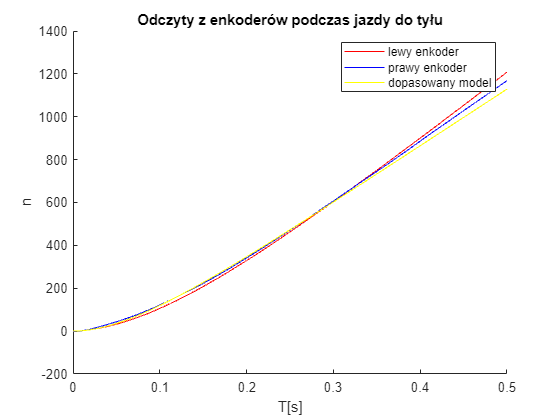



figure

model = tf([1480], [0.074 1 0])/32/pi*180;
[y, t_out] = step(model, 0.5);
A_read = readmatrix("mess_5000_2000hz_back_2.csv");
A = (A_read - 32000);
left_enc = -A(:,1);
right_enc = -A(:,2);
time_enc = linspace(0, 0.5, 1000)';
hold on
plot(time_enc, right_enc, 'r-')
plot(time_enc, left_enc, 'b-')
plot(t_out, y, 'y')
xlabel("T[s]")
ylabel("n")
title("Odczyty z enkoderów podczas jazdy do tyłu")
legend("lewy enkoder", "prawy enkoder", "dopasowany model")